Use the tipp from Leon that we dont have to do a double discretization we will use $I=64$ or smth and use this as $\frac{h}{2}$ and get $h$ from the same array but only every second entry.

clc
clear


randomfield = 1;
I_min = 64; 
I_max = 256; 
M = 10^3;
N = 10;
nu = 'infinity';
sigma = 0.5;
abs_err = zeros([(I_max-I_min)/2+1 1]);
rel_err = zeros([(I_max-I_min)/2+1 1]);
counter = 1;
for i=progress(I_min:2:I_max)
    % Only every second value of I since I/2 is used as main approx, and I
    % is the Richardson extrapolation grid
    x = linspace(0, 1, i+1);
    h = 1/i;
    x_half = zeros([i+1 1]);
    for k=1:i
        x_half(k) = (x(k+1) + x(k))/2;
    end
    if randomfield == 2
        C = Matern_specialcases_only(x_half, nu);
        [EVec, EVal] = eig(C);
        SV = zeros([i 1]);
        EVec = flip(EVec, 2);
        for k=1:i
            SV(k) = sqrt(EVal(i+1-k, i+1-k));
        end
    end    
    rng(1)
    x_hat = linspace(0, 1, N + 1);
    Y = normrnd(0, 1, [N M]);
    a = zeros([M i+1]);
    
    for sample=1:M
        if randomfield == 1
            ind = zeros([length(x) N]);
        
            % Calculate for every node in the I mesh
            for l=1:length(x)
                % Check for every node in I mesh if its in [x^(k-1), x^(k)]
                for r=2:N+1
                    if (x(l) >= x_hat(r-1) & x(l) <= x_hat(r))
                        ind(l, r-1) = Y(r-1, sample);
                    else
                        ind(l, r-1) = 0;
                    end
                end
            end
            
            stairs = crop(ind);
            a(sample, :) = 1 + 0.5*stairs;
        end
        if randomfield == 2
            inner = zeros([length(x) N]);
            for k=1:N
                inner(:, k) = SV(k)*Y(k).*EVec(:, k);
            end
            kappa = sum(inner, 2);
            a(sample, :) = exp(kappa);
        end
    end
    
    F = zeros([i+1 1]);
    for j=1:i+1
        F(j) = 4*pi^2*cos(2*pi*x_half(j));
    end
    
    u_h = zeros([M i+1]);
    
    for sample=1:M
        A = zeros([i+1 i+1]);
        for j=2:i
           A(j, j-1) = -a(sample, j-1)/(h^2);
           A(j, j) = (a(sample, j-1) + a(sample, j+1))/(h^2);
           A(j, j+1) = -a(sample, j+1)/(h^2);
        end
        
        u_h(sample, :) = A(2:i, :)\F(2:i);
    end
    
    QuantOfInt = zeros([M 1]);
    QuantOfInt2 = zeros([M 1]);
    for sample=1:M
        QuantOfInt(sample) = h*sum(u_h(sample, :));
        QuantOfInt2(sample) = 2*h*sum(u_h(sample, 1:2:end));
    end
    abs_err(counter) = abs(1/M*sum(QuantOfInt - QuantOfInt2));
    rel_err(counter) = abs_err(counter)/abs(1/M*sum(QuantOfInt2));
    counter = counter + 1;
end

Processing:  000%  |                                        | 0/97it [00:00:00<Inf:NaN:NaN, Inf it/s]




plot_array = ((I_min/2):(I_max/2));
p_rel = polyfit(log(plot_array(8:10:end)), log(rel_err(8:10:end)), 1)

p_rel =    -2.0435    1.2890


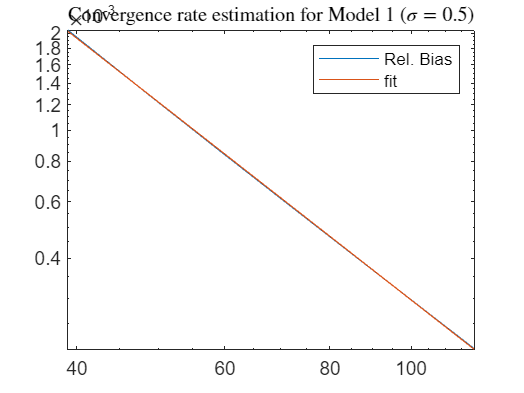

y_vals_rel = p_rel(2) + log(plot_array(8:10:end)) * p_rel(1);
%p_abs = polyfit(plot_array, (abs_err), 1)
%y_vals_abs = polyval(p_abs, plot_array);

loglog(plot_array(8:10:end), rel_err(8:10:end), plot_array(8:10:end), exp(y_vals_rel))
title('Convergence rate estimation for Model 1 ($\sigma=0.5$)', 'Interpreter', 'latex', fontsize=10)
legend('Rel. Bias', 'fit')
savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "p_est_M1_sig05")


%figure()
%plot(plot_array, abs_err, plot_array, y_vals_abs)
%legend('Abs. Bias', 'fit')